## Field Desorption Map

**Creation of field desorption map images and movies**

The field desorption map can be very informative since it highlights areas of variation in needed fields for the evaporation of matter and therefore comprises information such as the relative location of grain boundaries, differing phases, pole figures, and others. For the construction of a field desorption map, the x- and y-coordinates of the hit events on the detector are needed. Therefore, instead of the mostly used *.pos file, for example an *.epos file needs to be loaded. This is also possible with the function *posToTable*.

NOTE: The user has to select (*.epos) as displayed data type in the dialog box when loading a new file.

epos = posToTable; % loading of an *.epos file
 

**Creation of bin vectors**

In a further step, the detector plane is divided into bins. As distance variable (*dist*) the x- and y-coordinates of the detector are used. The *bin* variable must contain the bin width for both binning directions. It determines the resolution of the resulting field desorption map. Different bin widths are possible.

dist = [epos.detx, epos.dety]; % determination of the distance variables to be binned
bin = [0.5 0.5]; % bin width in x and y direction, in mm
mode = 'distance'; % 'distance' is the only possible mode in 2D and 3D
[binCenters, binEdges] = binVectorsFromDistance(dist,bin,mode); % creates bin centers and bin edges of the voxels
 

**Creation of field desorption map image**

With the MATLAB function *hist3*, a 3D histogram can be created. By specifying the indices of the detected hits (with the start value *'from'* and the end value *'to'*), the user can vary the number of hits contributing to the histogram and also in a way the time period of the measurement (by shifting the values). 

NOTE: The starting value must be smaller than the end value. Furthermore, the axes scaling changes with changing bin width and therefore, the units are arbitrary.

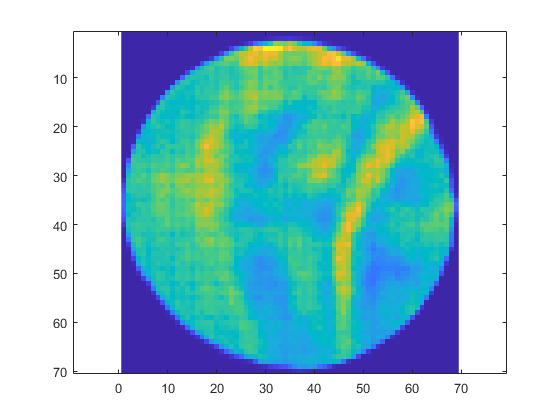

from = 1000000; % definition of the start index of detected ion
to = 10000000; % definition of the end index of detected ion, must be bigger than 'from' value
FDM = hist3([epos.detx(from:to), epos.dety(from:to)],binCenters); % creates array of the 3D histogram
imageFDM = imagesc(FDM); axis equal; % creates image of the field desorption map

**Creation of field desorption map movie**

With the creation of a field desorption map movie, the user can visualise the 'movement' of grain boundaries and other features during the measurement. 

This section functions without running the previous 2 sections. The inputs *frames*, *sample*, *RES*, and *fileName* are optional. The input *frames* defines the number of created field desoprtion map frames, which assemble the movie. Since the playing speed is set to 30 frames per second, this input affects the resulting movie length. The movie is created by stacking separate images. *sample* specifies the number of ions for each field desorption map frame. It is limited by the resolution of the field desorption map. The input *RES* represents the resolution, hence the number of pixels both in x and y direction. *fileName* defines the name of the movie file with an .avi suffix. It will be saved in the current folder.

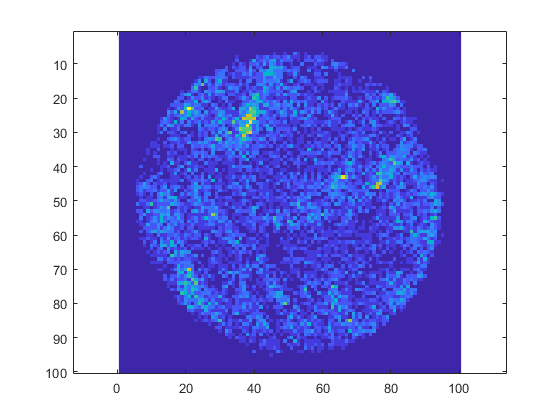

frames =  300; % number of frames of the movie
sample = 10000; % specification of sample size for each image
RES = 100; % resolution of the field desorption map (RES x RES), must be bigger than 1
fileName = "Test"; % definition of the file name, file will be saved in 'Current Folder'
movieFDM = movieCreateFieldDesorptionMap(epos.detx,epos.dety,frames,sample,RES,fileName);